# Clearance

close all
clear all
clc
colors = ["#EDB120", "#7E2F8E", "#77AC30"];


## Variables initialisation

M1 = 5;       %[kg]
M2 = 4;       %[kg]
M3 = 5;       %[kg]

J2 = 7;       %[kg*m^2]
J3 = 6;       %[kg*m^2]

M4 = 2;       %[kg]
R = 0.8;      %[m]
r = 0.6;      %[m]

k1 = 300;     %[N/m]
k2 = 350;     %[N/m]
k3 = 50;      %[N/m]

c1 = 0.5;     %[N*s/m]
c2 = 2;       %[N*s/m]
c3 = 10;      %[N*s/m]

g = 9.81; %[m/s²]

## Question 1 : Equation of Motion and System Matrices


%%% 1.a

%syms M1 M2 M3 J2 J3 M4 R r k1 k2 k3 c1 c2 c3
%clear M1 M2 M3 J2 J3 M4 R r k1 k2 k3 c1 c2 c3


%===============================================%
%===============================================%
%===============System matrices=================% 
%===============================================%
%===============================================%

%%Kinetic energy
M_phisic = diag([M1, M2, J2, M3, J3, M4]);
JacM = [1,0,0;  1,0,0   ;  0,1,0    ;
        1,0,-r  ;   0,0,1   ;   -1,0,r];
M_star = transpose(JacM) * M_phisic * JacM


%Elastic potential energy
K_phisic = diag([k1,k2,k3]);
Jack = [1,0,0;0,-R,-2*r;-1,0,r];
K_star = transpose(Jack) * K_phisic * Jack


% Gravitational potential energy
P = g*[M1; M2; M3; M4]
Lambda_y = [zeros(1,3),; zeros(1,3) ; zeros(1, 3) ; -1, 0, r ]

P_star = (P' * Lambda_y)'
dVgdx = 0.5*P_star

C_phisic = diag([c1,c2,c3]);
C_star = transpose(Jack) * C_phisic * Jack



%===============================================%
%===============================================%
%===============Equations of Motion=============% 
%===============================================%
%===============================================%

syms x_1(t) theta_2(t) theta_3(t) F(t)


Q = [F; 0; -r*F]               %Lagrangian component of the active forces

Qtot = [F; 0; -r*F] -0.5*P_star;

x = [x_1; theta_2; theta_3]     %Putting all the symbolic variales in a vector
dx = diff(x,t,1)                %1st derivative with respect to time
ddx = diff(x,t,2)               %2nd derivative with respect to time
%var = jacobian(ddx)

Mddx = M_star*ddx   %[kg.m/s²] == [N]

Cdx = C_star*dx     %[N.s/m*m/s] == [N]

Kx = K_star*x       %[N/m.m] == [N]

Ext = Q

EoM = Mddx + Cdx + Kx; %[N]

ODESdamped = Mddx + Cdx + Kx == Q

ODESundamped = Mddx + Kx == Q


## 1.a UNDAMPED SYSTEM



    
[V,D] = eig(M_star\K_star) %V => eigenvectors; D => eigenvalues lambda being the squares of w
        %solving the equation lambda^2*x = K/M * x
        %we want to find the eigenvalues and eigenvectors of [M_star]^(-1) * [K_star]
%%The acquired lambdas are actually the square of the natural frequencies
diagD = diag(D)
sorted_D = sort(diagD)
w_nats = sqrt( sort(diag(D)) )

mode_shapes = V ./ V(1,:) %%Normalization of mode shapes with respect to the x1_lambda = 1
mode_shapes_und = [mode_shapes(:,3), mode_shapes(:,2), mode_shapes(:,1)]  %%mode shapes reorganization
    %% We reorganize the mode shapes to match the rearrangement of the natural frequencies in increasing
X_1 = mode_shapes_und(:,1)
X_2 = mode_shapes_und(:,2)
X_3 = mode_shapes_und(:,3)

## Temporary 2



%{
w_nats = imag(lambdas_double)

filtered_w_nats = w_nats(w_nats>=0)

syms x1 x2 x3 x
x = [x1; x2; x3]
(lambdas_double(1)^2*M+K)*x

X_1 = solve( (lambdas_double(1)^2*M+K)*x == 0, x)
X_1.x1

X_2 = solve( [ (lambdas_double(2)^2*M+K)*x == 0, x~=0], x)
X_2.x1


%lambdas_double = double(lambd
% as)
%lambdas_double = double( lambdas)

eq1 = (lambda^2*M(1,1)+K(1,1)) * x1 + ( lambda^2*M(1,3)+K(1,3) ) * x3 == 0 

eq2 = ( lambda^2*M(2,2)+K(2,2) ) * x2 + K(3,2) * x3 == 0

eq3 = (lambda^2*M(1,3)+K(1,3)) * x1 + K(3,2)*x2 + ( lambda^2*M(3,3)+K(3,3) ) * x3  == 0


solve( eq1,eq2,eq3,x1,x2,x3)

%}

## 1.b DAMPED numcon State Space Form, eigenvalues and eigenvectors

B = [M_star, zeros(size(M_star)); zeros(size(M_star)), M_star]
D = [C_star, K_star; -M_star, zeros(size(M_star))]
A = (-B\D) %%State Matrix of the damped syste, we want to find the eigenvalues and eigenvectors of -[B]^(-1) * [D]


[Vd, Dd] = eig(A)  %% Dd is diagonal, even in the case undamped D were diagonal
lambdas = diag(Dd) %% for 3 Dof we have 6 lambdas
lambdas_sorted = sort(lambdas)  %% Ordering lambdas according to the increasing natural frequencies

Vd
X = Vd (4:6, :)   %The modes are in the lower part of the vector Vd
normX = X./(X(1,:))  %%Normalizing with respect to the component x1 ==1
normX = [normX(:,5),normX(:,6), normX(:,3), normX(:,4), normX(:,1), normX(:,2)]
    %Reordering the mode shapes with respect to the increasing order of the
    %obtained frequencies : index order 5 - 6 - 3 - 4 - 1 - 2
newnormX = [normX(:,5), normX(:,3), normX(:,1)]

absNewNormX = abs(newnormX)
angleNewNormX = angle(newnormX)

%mode_shapes_dam_abs = abs(mode_shapes_dam) .* exp(1i*angle(mode_shapes_dam))
 % angle returns in radians

%lambdas_dam_abs = abs(lambdas) .* exp(1i*angle(lambdas)) % angle returns in radians

w_damped = imag(lambdas_sorted( 2:2:end))

alpha = -real(lambdas_sorted(2:2:end))


h = alpha./(sqrt(w_damped.^2 + alpha.^2))  %%lightly damped from the results

h2 = alpha./w_nats %%lightly damped from the results, computed from another formula


## Rayleigh Damping estimation


const_mod = [1./(2.* w_nats), w_nats./2] \ h
alfa = const_mod(1);
beta = const_mod(2);
C_approx = alfa .* M + beta .*K


syms alpha beta

%%Eq = C == alpha.*M_phisic + beta.*K_phisic
solve(Eq)



## In progress


%% 1.c  Rayleigh Proportional Damping
alpha = real([lambdas(1), lambdas(3), lambdas(5)])

wd = imag([lambdas(1), lambdas(3), lambdas(5)]);  %%to have positive freq in ascending order and for lightly damped damped system are almost equal to natural freq

h = abs(alpha./(sqrt(wd.^2 + alpha.^2)));  %%lightly damped from the results

const_mod = [1./(2.* w_nat), w_nat./2]\h.';
alfa = const_mod(1);
beta = const_mod(2);
C_approx = alfa .* M + beta .* K;




## 2. Free motion of the system

%===============================%
% =====Initial conditions=======%
%===============================%
x_1_0       =   0.1;        %[m]
theta_2_0   =   pi/12;      %[rad]
theta_3_0   =   -pi/12;     %[rad]
v_1_0       =   1 ;         %[m/s]
v_ang_2_0   =   0.5;        %[rad/s]
v_ang_2_0   =   2;          %[rad/s]


clear C3 C2 C1 phi_3 phi_2 phi_1
syms  C3 C2 C1 phi_3 phi_2 phi_1

%Arbitrary for now, just for plotting purposes
C3 = -2;        %[-]
phi_3 = -3*pi; %[rad]
C1 = 1;
C2 = 2;
C3 = 1
phi_1 = 0;
phi_2 = 0;
phi_3 = 0;

time_end = 70; %[s]
num_elem = time_end * 1e4;
t = linspace(0,time_end, num_elem); %[s]

x_1_t = zeros(1,num_elem);      %[m]
theta_2_t = zeros(1,num_elem);  %[rad]
theta_3_t = zeros(1,num_elem);  %[rad]

X_Free_Vibr = [ x_1_t; theta_2_t; theta_3_t];   %%Concatenating all those vectors into X
C_unkn = [C1; C2; C3]



%X_Free_Vibr = X_Free_Vibr + exp(-alpha(i).*t) .* abs(newnormX(:,i)) .* C3 .* cos(w_damped(:).*t + phi_3 + angle(newnormX(:,i)) );



for i = 1:3
    %%Adding the participation of each variable of interest
    disp(i)
    X_Free_Vibr = X_Free_Vibr + exp(-alpha(i).*t) .* abs(newnormX(:,i)) .* C3 .* cos(w_damped(:).*t + phi_3 + angle(newnormX(:,i)) );
            %x_1_t = x_1_t + exp(-alpha(i)*t) .* abs(newnormX(1,i)) .* C3 .* cos(w_damped(1).*t + phi_3 + angle(newnormX(1,i)) );
            %theta_2_t = theta_2_t + exp(-alpha(i)*t) .* abs(newnormX(2,i)) .* C3 .* cos(w_damped(2).*t + phi_3 + angle(newnormX(2,i)) );
            %theta_3_t = theta_3_t + exp(-alpha(i)*t) .* abs(newnormX(3,i)) .* C3 .* cos(w_damped(3).*t + phi_3 + angle(newnormX(3,i)) );
end

X_Free_Vibr



## Initial conditions

C1 = 1;
C2 = 2;
C3 = 1

C3 = 1

phi_1 = pi;
phi_2 = 0;
phi_3 = pi/6;

x_1_0       =   0.1;        %[m]
theta_2_0   =   pi/12;      %[rad]
theta_3_0   =   -pi/12;     %[rad]
X_cond_0    =   [x_1_0; theta_2_0; theta_3_0]

X_cond_0 =     0.1000
    0.2618
   -0.2618



v_1_0       =   1 ;         %[m/s]
v_ang_2_0   =   0.5;        %[rad/s]
v_ang_3_0   =   2;        %[rad/s]

X_1_w_d_1 = exp(-alpha(1).*t) .* abs(newnormX(:,1)) .* C1 .* cos(w_damped(:).*t + phi_1 + angle(newnormX(:,1)) )

X_1_w_d_1 =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9997   -0.9997   -0.9997   -0.9997   -0.9997   -0.9997
   -2.1712   -2.1712   -2.1711   -2.1710   -2.1709   -2.1708   -2.1707   -2.1706   -2.1705   -2.1705   -2.1704   -2.1703   -2.1702   -2.1701   -2.1700   -2.1699   -2.1698   -2.1697   -2.1696   -2.1695   -2.1694   -2.1693   -2.1692   -2.1691   -2.1691   -2.1690   -2.1689   -2.1688   -2.1687   -2.1686   -2.1685   -2.1684   -2.1683   -2.1682   -2.1681   -2.1680   -2.1679   -2.1678   -2.1677   -2.1675   -2.1674   -2.1673   -2.1672   -2.1671   -2.1670   -2.1669   -2.1668   -2.1667   -2.1

X_1_w_d_2 = exp(-alpha(2).*t) .* abs(newnormX(:,2)) .* C2 .* cos(w_damped(:).*t + phi_2 + angle(newnormX(:,2)) )

X_1_w_d_2 =     2.0000    1.9999    1.9999    1.9998    1.9998    1.9997    1.9996    1.9996    1.9995    1.9994    1.9994    1.9993    1.9993    1.9992    1.9991    1.9991    1.9990    1.9989    1.9989    1.9988    1.9988    1.9987    1.9986    1.9986    1.9985    1.9984    1.9984    1.9983    1.9983    1.9982    1.9981    1.9981    1.9980    1.9979    1.9979    1.9978    1.9978    1.9977    1.9976    1.9976    1.9975    1.9974    1.9974    1.9973    1.9972    1.9972    1.9971    1.9971    1.9970    1.9969
   -0.4647   -0.4647   -0.4648   -0.4649   -0.4649   -0.4650   -0.4650   -0.4651   -0.4652   -0.4652   -0.4653   -0.4653   -0.4654   -0.4655   -0.4655   -0.4656   -0.4656   -0.4657   -0.4658   -0.4658   -0.4659   -0.4659   -0.4660   -0.4661   -0.4661   -0.4662   -0.4662   -0.4663   -0.4663   -0.4664   -0.4665   -0.4665   -0.4666   -0.4666   -0.4667   -0.4667   -0.4668   -0.4669   -0.4669   -0.4670   -0.4670   -0.4671   -0.4672   -0.4672   -0.4673   -0.4673   -0.4674   -0.4674   -0.4

X_1_w_d_3 = exp(-alpha(2).*t) .* abs(newnormX(:,2)) .* C3 .* cos(w_damped(:).*t + phi_3 + angle(newnormX(:,3)) )

X_1_w_d_3 =     0.8660    0.8660    0.8659    0.8658    0.8658    0.8657    0.8656    0.8656    0.8655    0.8654    0.8654    0.8653    0.8652    0.8652    0.8651    0.8650    0.8650    0.8649    0.8648    0.8648    0.8647    0.8646    0.8646    0.8645    0.8644    0.8643    0.8643    0.8642    0.8641    0.8641    0.8640    0.8639    0.8639    0.8638    0.8637    0.8637    0.8636    0.8635    0.8635    0.8634    0.8633    0.8633    0.8632    0.8631    0.8631    0.8630    0.8629    0.8629    0.8628    0.8627
   -0.2281   -0.2280   -0.2280   -0.2279   -0.2279   -0.2278   -0.2278   -0.2277   -0.2277   -0.2276   -0.2276   -0.2275   -0.2275   -0.2274   -0.2274   -0.2273   -0.2273   -0.2272   -0.2272   -0.2271   -0.2271   -0.2270   -0.2270   -0.2269   -0.2269   -0.2268   -0.2268   -0.2267   -0.2267   -0.2266   -0.2266   -0.2265   -0.2265   -0.2264   -0.2263   -0.2263   -0.2262   -0.2262   -0.2261   -0.2261   -0.2260   -0.2260   -0.2259   -0.2259   -0.2258   -0.2258   -0.2257   -0.2257   -0.2






syms C_1 C_2 C_3 Phi_1 Phi_2 Phi_3
C_C = [C_1; C_2; C_3]

$$C\_C = \left(\begin{array}{c} C_{1}\\ C_{2}\\ C_{3} \end{array}\right)$$

Phi = [Phi_1; Phi_2; Phi_3]

$$Phi = \left(\begin{array}{c} \Phi_{1}\\ \Phi_{2}\\ \Phi_{3} \end{array}\right)$$

eq_cond_x_1         = sum( ( C_C .* absNewNormX(1,:)' ) .* cos( Phi + angleNewNormX(1,:)' ) )  == x_1_0

$$eq\_cond\_x\_1 = C_{1}\,\cos\left(\Phi_{1}\right)+C_{2}\,\cos\left(\Phi_{2}\right)+C_{3}\,\cos\left(\Phi_{3}\right)=\frac{1}{10}$$

eq_cond_theta_2     = sum( ( C_C .* absNewNormX(2,:)' ) .* cos( Phi + angleNewNormX(2,:)' ) )  == theta_2_0   

$$eq\_cond\_theta\_2 = \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}+\frac{2596463732872441}{36028797018963968}\right)}{2251799813685248}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{6319741833370221}{2251799813685248}\right)}{9007199254740992}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{6760270012660601}{2251799813685248}\right)}{281474976710656}=\frac{\pi }{12}$$

eq_cond_theta_3     = sum( ( C_C .* absNewNormX(3,:)' ) .* cos( Phi + angleNewNormX(3,:)' ) )  == theta_3_0

$$eq\_cond\_theta\_3 = \frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{1266828259271581}{2251799813685248}\right)}{36028797018963968}+\frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}+\frac{2933453089654753}{36028797018963968}\right)}{281474976710656}+\frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{2561317537478021}{18014398509481984}\right)}{562949953421312}=-\frac{\pi }{12}$$

%solve(eq_cond0)

% Delay induced by the damping
shift = atan( mod(w_damped./alpha, pi) )

shift =     1.0681
    1.1858
    1.2284



eq_cond_v_1     = sum( ( C_C .* absNewNormX(1,:)' ) .* cos( Phi + angleNewNormX(1,:)' - shift) ) == v_1_0

$$eq\_cond\_v\_1 = C_{2}\,\cos\left(\Phi_{2}-\frac{5340563475179447}{4503599627370496}\right)+C_{3}\,\cos\left(\Phi_{3}-\frac{2766190484248759}{2251799813685248}\right)+C_{1}\,\cos\left(\Phi_{1}-\frac{4810101339164699}{4503599627370496}\right)=1$$

eq_cond_v_ang_2 = sum( ( C_C .* absNewNormX(2,:)' ) .* cos( Phi + angleNewNormX(2,:)' - shift) ) == v_ang_2_0

$$eq\_cond\_v\_ang\_2 = \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}-\frac{35884346980445151}{36028797018963968}\right)}{2251799813685248}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{1997039764205921}{1125899906842624}\right)}{281474976710656}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{7298920191560995}{4503599627370496}\right)}{9007199254740992}=\frac{1}{2}$$

eq_cond_v_ang_3 = sum( ( C_C .* absNewNormX(3,:)' ) .* cos( Phi + angleNewNormX(3,:)' - shift) ) == v_ang_3_0

$$eq\_cond\_v\_ang\_3 = \frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{24690841411468093}{18014398509481984}\right)}{562949953421312}+\frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{7874219993722609}{4503599627370496}\right)}{36028797018963968}+\frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}-\frac{35547357623662839}{36028797018963968}\right)}{281474976710656}=2$$

% 
% eq_cond_v_1 = ( C_C .* absNewNormX(1,:) ) * cos( Phi + angleNewNormX(1,:) - shift' )'  == v_1_0;
% eq_cond_v_ang_2 = ( C_C .* absNewNormX(2,:) ) * cos( Phi + angleNewNormX(2,:) - shift' )'  == v_ang_2_0;
% eq_cond_v_ang_3 = ( C_C .* absNewNormX(3,:) ) * cos( Phi + angleNewNormX(3,:) - shift' )'  == v_ang_3_0;
% 
eq_bundle = [eq_cond_x_1, eq_cond_theta_2, eq_cond_theta_3, eq_cond_v_1, eq_cond_v_ang_2, eq_cond_v_ang_3]

$$eq\_bundle = \left(\begin{array}{cccccc} C_{1}\,\cos\left(\Phi_{1}\right)+C_{2}\,\cos\left(\Phi_{2}\right)+C_{3}\,\cos\left(\Phi_{3}\right)=\frac{1}{10} & \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}+\frac{2596463732872441}{36028797018963968}\right)}{2251799813685248}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{6319741833370221}{2251799813685248}\right)}{9007199254740992}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{6760270012660601}{2251799813685248}\right)}{281474976710656}=\frac{\pi }{12} & \frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{1266828259271581}{2251799813685248}\right)}{36028797018963968}+\frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}+\frac{2933453089654753}{36028797018963968}\right)}{281474976710656}+\frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{2561317537478021}{18014398509481984}\right)}{562949953421312}=-\frac{\pi }{12} & C_{2}\,\cos\left(\Phi_{2}-\frac{5340563475179447}{4503599627370496}\right)+C_{3}\,\cos\left(\Phi_{3}-\frac{2766190484248759}{2251799813685248}\right)+C_{1}\,\cos\left(\Phi_{1}-\frac{4810101339164699}{4503599627370496}\right)=1 & \frac{4901924296910687\,C_{1}\,\cos\left(\Phi_{1}-\frac{35884346980445151}{36028797018963968}\right)}{2251799813685248}+\frac{5345020887469603\,C_{3}\,\cos\left(\Phi_{3}+\frac{1997039764205921}{1125899906842624}\right)}{281474976710656}+\frac{2215917559648199\,C_{2}\,\cos\left(\Phi_{2}+\frac{7298920191560995}{4503599627370496}\right)}{9007199254740992}=\frac{1}{2} & \frac{6984389378930435\,C_{3}\,\cos\left(\Phi_{3}-\frac{24690841411468093}{18014398509481984}\right)}{562949953421312}+\frac{1910210710385409\,C_{2}\,\cos\left(\Phi_{2}-\frac{7874219993722609}{4503599627370496}\right)}{36028797018963968}+\frac{901356901096913\,C_{1}\,\cos\left(\Phi_{1}-\frac{35547357623662839}{36028797018963968}\right)}{281474976710656}=2 \end{array}\right)$$

solve(eq_bundle, [C_1, C_2, C_3, Phi_1, Phi_2, Phi_3])
% 

% Overlapped plots
figure()
plot(t,X_1_w_d_1 + X_1_w_d_2 + X_1_w_d_3)
titleStr = "x_1_{w_d1}";
title(titleStr);
grid on;

ylabel("Amplitude [-]");
xlabel("time [s]");
legend("x_1(t)", "theta_2(t)", "theta_3(t)");


## Temporary again

% Define the symbolic variables
syms C1 C2 C3 Phi1 Phi2 Phi3


% Define the vectors
C = [C1; C2; C3];
Phi = [Phi1; Phi2; Phi3];

% Define the equations involving vector products
% Example equations (replace these with your actual equations)
eq1 = dot(C, Phi) == 8;             % Dot product of C and Phi
eq2 = C.' * Phi  == 2 % Cross product component (C1*Phi2 - C2*Phi1)

$$eq2 = C_{1}\,\Phi_{1}+C_{2}\,\Phi_{2}+C_{3}\,\Phi_{3}=2$$

eq3 = norm(C) == sqrt(14);          % Norm of vector C
eq4 = Phi(1) + Phi(2) + Phi(3) == 3; % Sum of elements of Phi
eq5 = C(1) + 2 * C(2) + 3 * C(3) == 4; % Linear combination of C
eq6 = C.' * [1; 1; 1] == 5;         % Another linear combination of C

% Collect the equations in a vector
equations = [eq1, eq2, eq3, eq4, eq5, eq6];

% Solve the system of equations
solutions = solve(equations, [C1, C2, C3, Phi1, Phi2, Phi3])

solutions = struct with fields:
      C1: [0×1 sym]
      C2: [0×1 sym]
      C3: [0×1 sym]
    Phi1: [0×1 sym]
    Phi2: [0×1 sym]
    Phi3: [0×1 sym]



% Display the solutions
C1_sol = solutions.C1

 
C1_sol =
 
Empty sym: 0-by-1
 


C2_sol = solutions.C2

 
C2_sol =
 
Empty sym: 0-by-1
 


C3_sol = solutions.C3

 
C3_sol =
 
Empty sym: 0-by-1
 


Phi1_sol = solutions.Phi1

 
Phi1_sol =
 
Empty sym: 0-by-1
 


Phi2_sol = solutions.Phi2

 
Phi2_sol =
 
Empty sym: 0-by-1
 


Phi3_sol = solutions.Phi3

 
Phi3_sol =
 
Empty sym: 0-by-1
 


## Plots

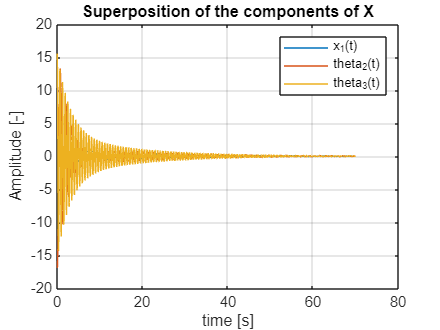


% Overlapped plots
figure()
for i = 1:3
    plot(t,X_Free_Vibr(i,:))
    titleStr = "Superposition of the components of X";
    title(titleStr);
    hold on;
    
    grid on;
end
ylabel("Amplitude [-]");
xlabel("time [s]");
legend("x_1(t)", "theta_2(t)", "theta_3(t)");

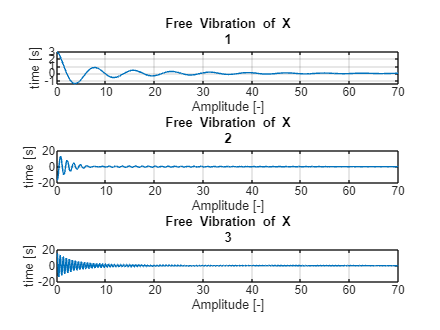



% Non overlapped plots
figure()
for i = 1:3
    subplot(3,1,i);
    plot(t,X_Free_Vibr(i,:));
    titleStr = [ "Free Vibration of X_", i];
    xlabel("Amplitude [-]");
    ylabel("time [s]");
    grid on;
    title(titleStr);
end